# **Análise de sinais**

## Boas Práticas

clc;                % limpa a tela do workspace
clear all;          % limpa todas as variáveis
close all;          % fecha todas as figuras

## Como ler e ouvir um arquivo wav

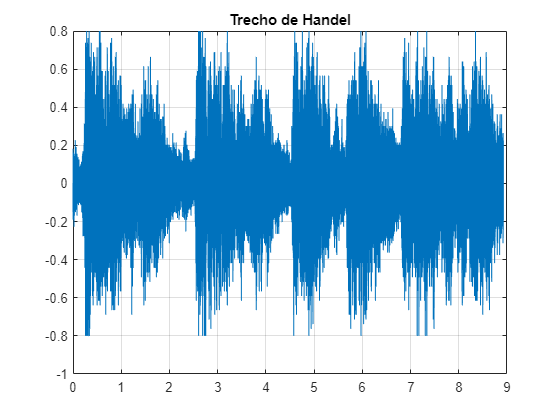

%%%%% Escrita de arquivo wav
load handel.mat;
filename = "handel.wav";
audiowrite(filename, y, Fs);
clear y Fs
%%%%% Leitura de arquivo .wav - audioread
[y , Fs] = audioread("handel.wav");
%%%%% Ouvir arquivo wav
sound(y, Fs);
%%%%% Visualização do sinal no tempo

%%% Pré-processamento

Ns = length(y);                 % número de amostras
Ts = 1/Fs;                      % intervalo entre amosstras
Tempo_final = Ns * Ts;          % tempo total

tempo = linspace(0,Tempo_final, Ns);
%%% criando o gráfico
figure(1)
plot(tempo, y);
grid;
xlabel = "Tempo em segundos";
ylabel = "Amplitude do sinal";
title("Trecho de Handel");

%%%%%% Trabalhando com trechos do sinal
t_inicial = 2.5;                    % tempo de início do trecho
t_final = 4.5;                      % tempo final do trecho

indice_inicial = ceil(2.5/Ts)       % começo do trecho

indice_inicial = 20480

indice_final = ceil(4.5/Ts)         %fim do trecho

indice_final = 36864

sound(y(indice_inicial:indice_final), Fs);

## Como determinar e ouvir o Fourier de um sinal

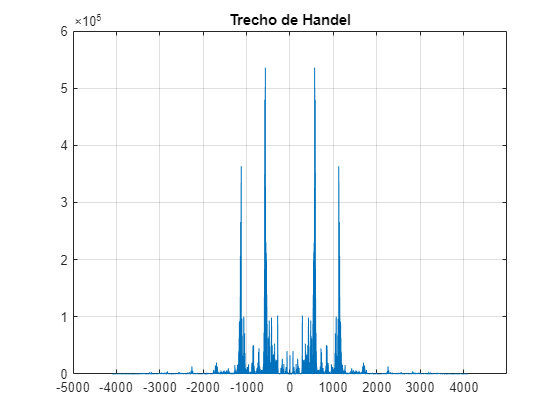

%%%%% Análise de Fourier - FFT - Fast Fourier Transform
Y_f = fftshift(fft(y));                 % transforma para o domínio da frequência

%%% Pré-processamento
frequencia = linspace(-Fs/2,Fs/2,Ns);
%%% Criando o gráfico
figure(2)
plot(frequencia, abs(Y_f).^2);
grid;
xlabel = "Frequência em Hz";
ylabel = "Módulo do sinal";
title("Trecho de Handel");

## **Como utilizar a integral de convolução**